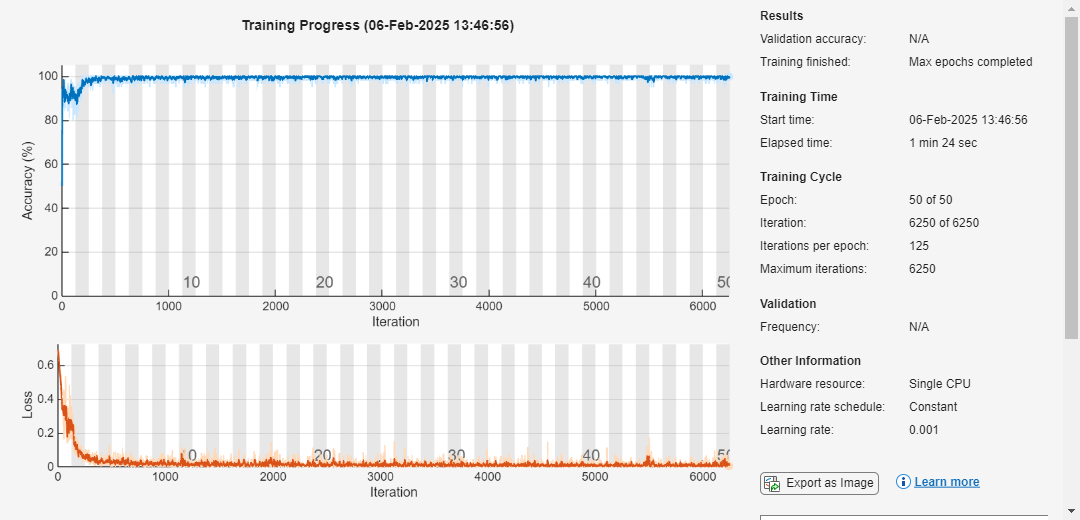

✅ Fold 1 Accuracy: 99.40%


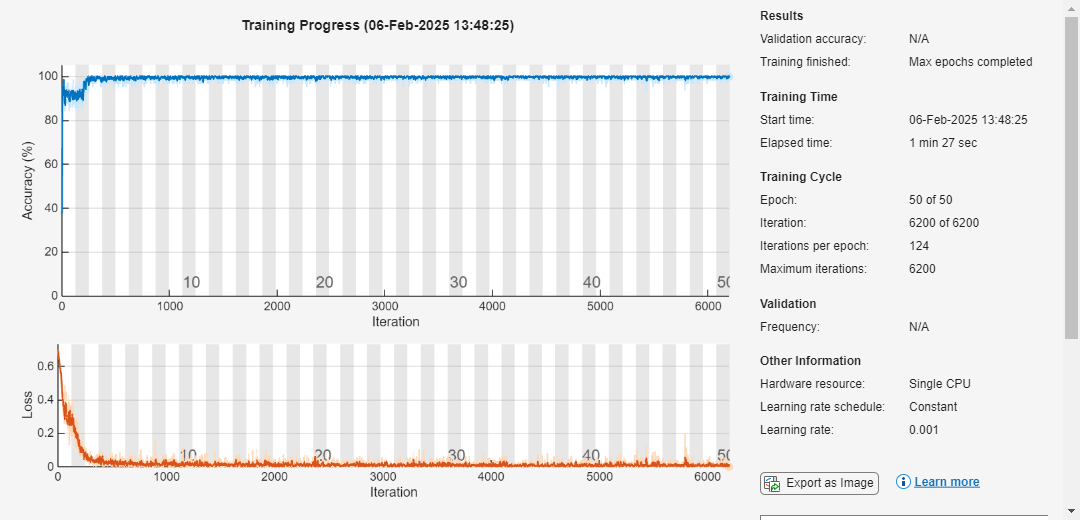

✅ Fold 2 Accuracy: 99.90%


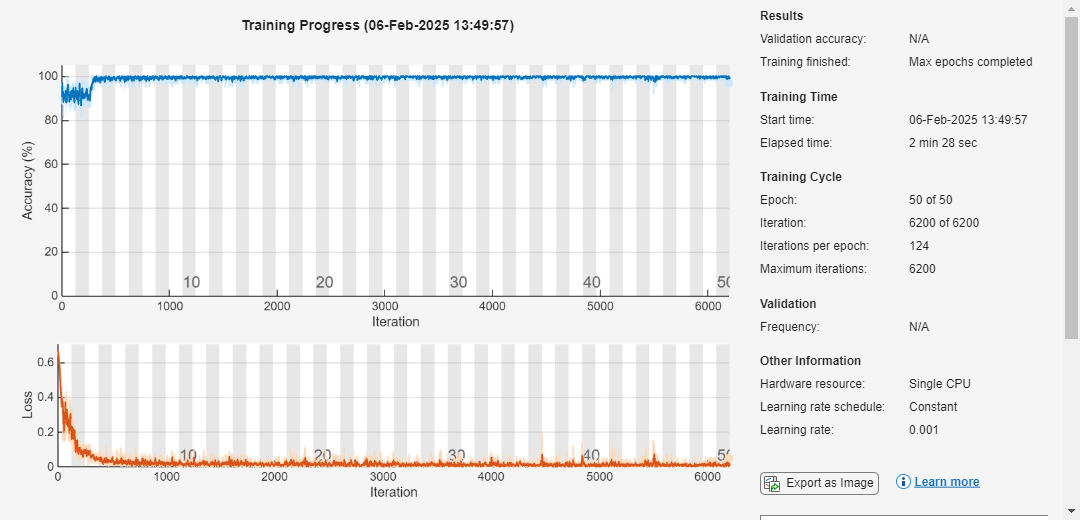

✅ Fold 3 Accuracy: 99.15%


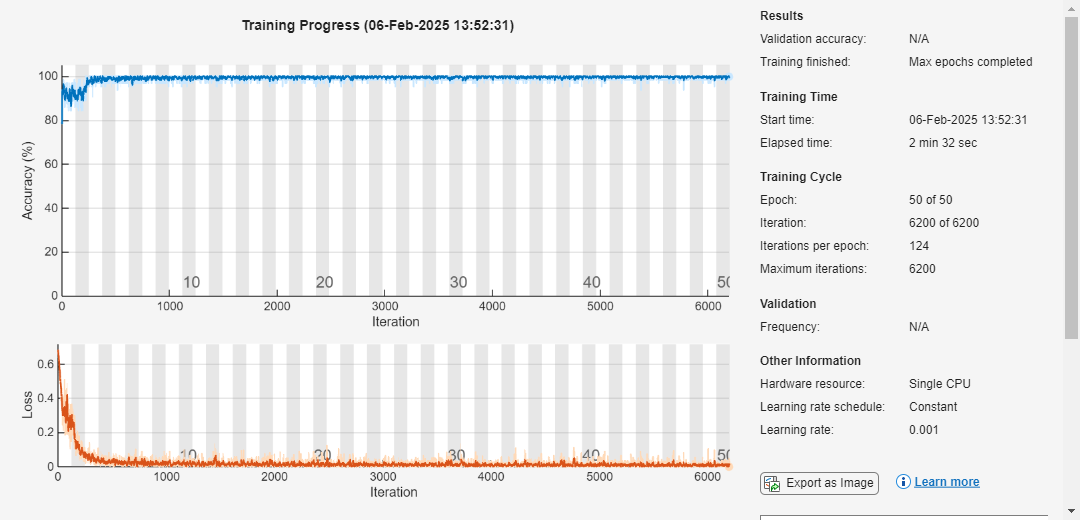

✅ Fold 4 Accuracy: 99.45%


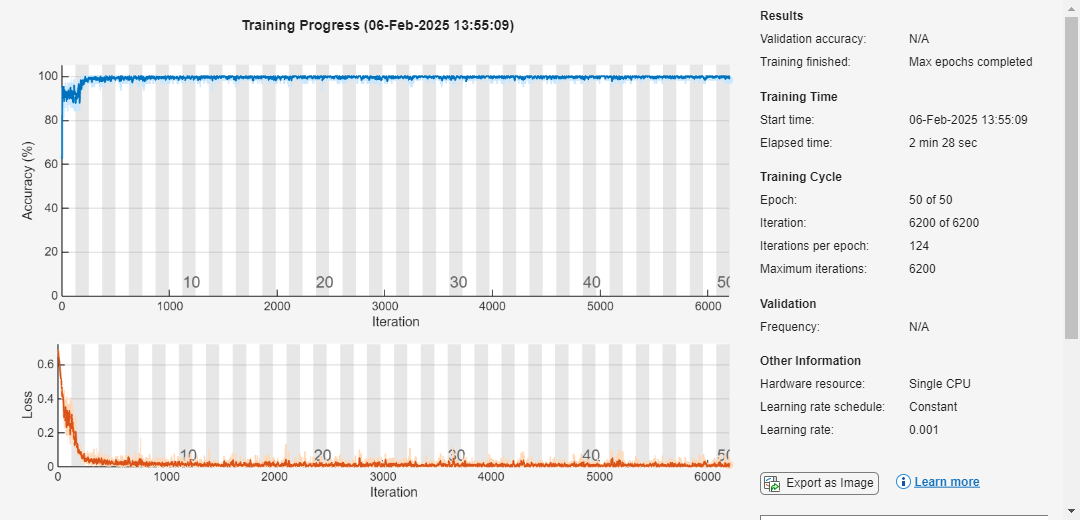

✅ Fold 5 Accuracy: 99.80%


filename = "C:\Users\minot\Downloads\Energy_consumption (1).xlsx";
data = readtable(filename, 'PreserveVariableNames', true);
data.Properties.VariableNames = strtrim(data.Properties.VariableNames);
time = datetime(data.Timestamp, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
power = movmean(data.Avg_Voltage .* data.Avg_Current .* data.("Power factor"), 5); 
frequency = movmean(data.Freq, 5);
power_threshold = mean(power) + 2 * std(power);
freq_threshold = mean(frequency) + 2 * std(frequency);
labels = categorical((power > power_threshold) | (frequency > freq_threshold), ...
                     [false true], ["Normal", "Anomaly"]);

features = [hour(time), minute(time), power, frequency]; 
features = normalize(features, 'range'); 
k = 5;
cv = cvpartition(size(features, 1), 'KFold', k);
accuracies = zeros(k, 1);
trainingLosses = cell(k, 1); 

for fold = 1:k
    XTrain = features(training(cv, fold), :);
    YTrain = labels(training(cv, fold));
    XTest = features(test(cv, fold), :);
    YTest = labels(test(cv, fold));
    XTrain = arrayfun(@(i) XTrain(i, :)', 1:size(XTrain, 1), 'UniformOutput', false);
    XTest = arrayfun(@(i) XTest(i, :)', 1:size(XTest, 1), 'UniformOutput', false);
    layers = [
        sequenceInputLayer(size(features, 2)) 
        lstmLayer(50, 'OutputMode', 'last')   
        fullyConnectedLayer(32)
        reluLayer
        dropoutLayer(0.2)
        fullyConnectedLayer(16)
        reluLayer
        dropoutLayer(0.2)
        fullyConnectedLayer(2) 
        softmaxLayer
        classificationLayer
    ];
    options = trainingOptions('adam', ...
        'MaxEpochs', 50, ...
        'MiniBatchSize', 64, ...
        'InitialLearnRate', 0.001, ...
        'Shuffle', 'every-epoch', ...
        'Verbose', false, ...
        'Plots', 'training-progress', ...
        'OutputFcn', @(info) trackLoss(info, fold)); % Track loss
    net = trainNetwork(XTrain, YTrain, layers, options);
    YPred = classify(net, XTest);
    accuracy = sum(YPred == YTest) / numel(YTest) * 100;
    accuracies(fold) = accuracy;
    fprintf("Fold %d Accuracy: %.2f%%\n", fold, accuracy);
end

avgAccuracy = mean(accuracies);
fprintf("\n Average Model Accuracy (after %d-fold cross-validation): %.2f%%\n", k, avgAccuracy);


✅ Average Model Accuracy (after 5-fold cross-validation): 99.54%


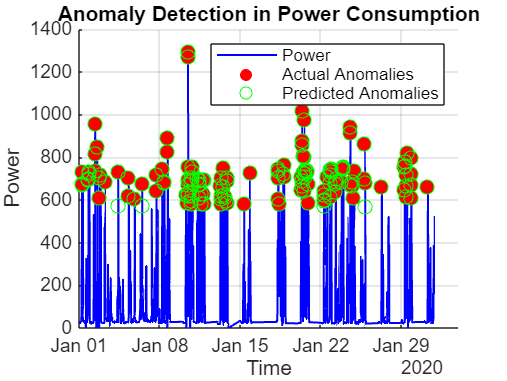

testIndices = test(cv, k); 
testTime = time(testIndices);
testPower = power(testIndices);
actualAnomalyIdx = (labels(testIndices) == "Anomaly");
predictedAnomalyIdx = (YPred == "Anomaly");

figure;
hold on;
plot(testTime, testPower, 'b', 'LineWidth', 1); 
scatter(testTime(actualAnomalyIdx), testPower(actualAnomalyIdx), 50, 'r', 'filled'); 
scatter(testTime(predictedAnomalyIdx), testPower(predictedAnomalyIdx), 50, 'g', 'o'); 
legend('Power', 'Actual Anomalies', 'Predicted Anomalies');
xlabel('Time');
ylabel('Power');
title('Anomaly Detection in Power Consumption');
grid on;
hold off;


windowSize = 10; 
figure; hold on;
colors = lines(k); 

for fold = 1:k
    smoothedLoss = movmean(trainingLosses{fold}, windowSize);
    plot(smoothedLoss, 'Color', colors(fold, :), 'LineWidth', 2);
end

xlabel('Epochs');
ylabel('Training Loss');
title('Smoothed Learning Curves for All 5 Folds');
legend(arrayfun(@(x) sprintf('Fold %d', x), 1:k, 'UniformOutput', false));

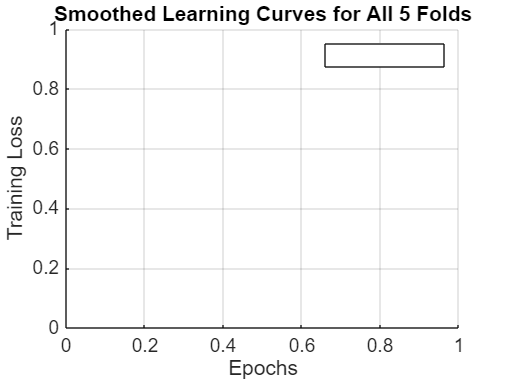

grid on;
hold off;